syms xi et zt
assume([xi,et,zt], 'real')

dim = 3;
P_Nodes = Node_Pyramid14()

$$P\_Nodes = \left(\begin{array}{ccc} -1 & -1 & 0\\ 1 & -1 & 0\\ 1 & 1 & 0\\ -1 & 1 & 0\\ 0 & 0 & 1\\ 0 & -1 & 0\\ 1 & 0 & 0\\ 0 & 1 & 0\\ -1 & 0 & 0\\ -\frac{1}{2} & -\frac{1}{2} & \frac{1}{2}\\ \frac{1}{2} & -\frac{1}{2} & \frac{1}{2}\\ \frac{1}{2} & \frac{1}{2} & \frac{1}{2}\\ -\frac{1}{2} & \frac{1}{2} & \frac{1}{2}\\ 0 & 0 & 0 \end{array}\right)$$

SF = @SF_Pyramid14;

NN = size(P_Nodes,1);
DMat = sym(zeros(NN));
D0N = simplify(SF(xi,et,zt));
for i = 1:NN
    DMat(i,:) = SF(P_Nodes(i,1),P_Nodes(i,2),P_Nodes(i,3));
    if(any(isnan(double(DMat)),'all'))
        DMat(i,:) = limit(...
            subs(D0N,[xi,et],[P_Nodes(i,1),P_Nodes(i,2)]),...
            zt, P_Nodes(i,3));
        warning('using zeta''s limit')
    end
end

DMat

$$DMat = \left(\begin{array}{cccccccccccccc} 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 \end{array}\right)$$

assert(logical(norm(DMat - eye(size(DMat))) == 0))


D0N = simplify(SF(xi,et,zt))

D1N = simplify([diff(D0N,xi);diff(D0N,et);diff(D0N,zt)])

if(dim == 2)
    D2N = simplify([diff(D0N,xi,xi);diff(D0N,xi,et);diff(D0N,et,et)])
elseif(dim == 3)
    D2N = simplify([diff(D0N,xi,xi);diff(D0N,et,et);diff(D0N,zt,zt);...
        diff(D0N,xi,et);diff(D0N,et,zt);diff(D0N,xi,zt)])
end

if(dim == 2)
    D3N = simplify([diff(D0N,xi,xi,xi);diff(D0N,xi,xi,et);diff(D0N,xi,et,et);diff(D0N,et,et,et)])
elseif(dim == 3)
    D3N = simplify([...
        diff(D0N,xi,xi,xi);diff(D0N,et,et,et);diff(D0N,zt,zt,zt);...
        diff(D0N,xi,xi,et);diff(D0N,xi,et,et);diff(D0N,et,et,zt);...
        diff(D0N,et,zt,zt);diff(D0N,xi,zt,zt);diff(D0N,xi,xi,zt);...
        diff(D0N,xi,et,zt)])
end

% D0NCode = regexprep(fortran(D0N),...
%     ["D0N", "D([+-0])"], ...
%     ["v", "e$1"])
% D1NCode = regexprep(fortran(D1N),...
%     ["D1N", "D([+-0])"], ...
%     ["v", "e$1"])

D0NCode = regexprep(ccode(D0N),...
    ["D0N", "\[(\d+)\]\[(\d+)\]"],...
    ["v","($1,$2)"])

D0NCode =     '  v(0,0) = (et*xi*(zt*2.0-1.0)*(zt*2.0-2.0)*1.0/pow(zt-1.0,4.0)*(et+zt-1.0)*(xi+zt-1.0))/8.0;
       v(0,1) = (et*xi*(zt*2.0-1.0)*(zt*2.0-2.0)*1.0/pow(zt-1.0,4.0)*(et+zt-1.0)*(xi-zt+1.0))/8.0;
       v(0,2) = (et*xi*(zt*2.0-1.0)*(zt*2.0-2.0)*1.0/pow(zt-1.0,4.0)*(et-zt+1.0)*(xi-zt+1.0))/8.0;
       v(0,3) = (et*xi*(zt*2.0-1.0)*(zt*2.0-2.0)*1.0/pow(zt-1.0,4.0)*(xi+zt-1.0)*(et-zt+1.0))/8.0;
       v(0,4) = zt*(zt*2.0-1.0);
       v(0,5) = et*(zt*2.0-1.0)*(zt*2.0-2.0)*1.0/pow(zt-1.0,4.0)*(et+zt-1.0)*(xi+zt-1.0)*(xi-zt+1.0)*(-1.0/4.0);
       v(0,6) = xi*(zt*2.0-1.0)*(zt*2.0-2.0)*1.0/pow(zt-1.0,4.0)*(et+zt-1.0)*(et-zt+1.0)*(xi-zt+1.0)*(-1.0/4.0);
       v(0,7) = et*(zt*2.0-1.0)*(zt*2.0-2.0)*1.0/pow(zt-1.0,4.0)*(xi+zt-1.0)*(et-zt+1.0)*(xi-zt+1.0)*(-1.0/4.0);
       v(0,8) = xi*(zt*2.0-1.0)*(zt*2.0-2.0)*1.0/pow(zt-1.0,4.0)*(et+zt-1.0)*(xi+zt-1.0)*(et-zt+1.0)*(-1.0/4.0);
       v(0,9) = zt*(zt*2.0-2.0)*1.0/pow(zt-1.0,2.0)*(et+zt-1.0)*(xi+zt-1.0)*(-1.0/2.0);
       v(0,10) = (zt*

D1NCode = regexprep(ccode(D1N),...
    ["D1N", "\[(\d+)\]\[(\d+)\]"],...
    ["v","($1,$2)"])

D1NCode =     '  v(0,0) = (et*(zt*2.0-1.0)*1.0/pow(zt-1.0,3.0)*(et+zt-1.0)*(xi*2.0+zt-1.0))/4.0;
       v(0,1) = (et*(zt*2.0-1.0)*1.0/pow(zt-1.0,3.0)*(xi*2.0-zt+1.0)*(et+zt-1.0))/4.0;
       v(0,2) = (et*(zt*2.0-1.0)*1.0/pow(zt-1.0,3.0)*(xi*2.0-zt+1.0)*(et-zt+1.0))/4.0;
       v(0,3) = (et*(zt*2.0-1.0)*1.0/pow(zt-1.0,3.0)*(et-zt+1.0)*(xi*2.0+zt-1.0))/4.0;
       v(0,5) = -et*xi*(zt*2.0-1.0)*1.0/pow(zt-1.0,3.0)*(et+zt-1.0);
       v(0,6) = (zt*2.0-1.0)*1.0/pow(zt-1.0,3.0)*(xi*2.0-zt+1.0)*(zt*2.0+et*et-zt*zt-1.0)*(-1.0/2.0);
       v(0,7) = -et*xi*(zt*2.0-1.0)*1.0/pow(zt-1.0,3.0)*(et-zt+1.0);
       v(0,8) = (zt*2.0-1.0)*1.0/pow(zt-1.0,3.0)*(xi*2.0+zt-1.0)*(zt*2.0+et*et-zt*zt-1.0)*(-1.0/2.0);
       v(0,9) = -(zt*(et+zt-1.0))/(zt-1.0);
       v(0,10) = (zt*(et+zt-1.0))/(zt-1.0);
       v(0,11) = -(zt*(et-zt+1.0))/(zt-1.0);
       v(0,12) = (zt*(et-zt+1.0))/(zt-1.0);
       v(0,13) = xi*(zt*2.0-1.0)*1.0/pow(zt-1.0,3.0)*(zt*2.0+et*et-zt*zt-1.0)*2.0;
       v(1,0) = (xi*(zt*2.0-1.0)*1.0/pow

try
    D2NCode = regexprep(ccode(D2N),...
        ["D2N", "\[(\d+)\]\[(\d+)\]"],...
        ["v","($1,$2)"])
catch e
    e
end

D2NCode =     '  v(0,0) = (et*(zt*2.0-1.0)*(zt*2.0-2.0)*1.0/pow(zt-1.0,4.0)*(et+zt-1.0))/4.0;
       v(0,1) = (et*(zt*2.0-1.0)*(zt*2.0-2.0)*1.0/pow(zt-1.0,4.0)*(et+zt-1.0))/4.0;
       v(0,2) = (et*(zt*2.0-1.0)*(zt*2.0-2.0)*1.0/pow(zt-1.0,4.0)*(et-zt+1.0))/4.0;
       v(0,3) = (et*(zt*2.0-1.0)*(zt*2.0-2.0)*1.0/pow(zt-1.0,4.0)*(et-zt+1.0))/4.0;
       v(0,5) = et*(zt*2.0-1.0)*(zt*2.0-2.0)*1.0/pow(zt-1.0,4.0)*(et+zt-1.0)*(-1.0/2.0);
       v(0,6) = (zt*2.0-1.0)*(zt*2.0-2.0)*1.0/pow(zt-1.0,4.0)*(et+zt-1.0)*(et-zt+1.0)*(-1.0/2.0);
       v(0,7) = et*(zt*2.0-1.0)*(zt*2.0-2.0)*1.0/pow(zt-1.0,4.0)*(et-zt+1.0)*(-1.0/2.0);
       v(0,8) = (zt*2.0-1.0)*(zt*2.0-2.0)*1.0/pow(zt-1.0,4.0)*(et+zt-1.0)*(et-zt+1.0)*(-1.0/2.0);
       v(0,13) = (zt*2.0-1.0)*(zt*2.0-2.0)*1.0/pow(zt-1.0,4.0)*(et+zt-1.0)*(et-zt+1.0);
       v(1,0) = (xi*(zt*2.0-1.0)*(zt*2.0-2.0)*1.0/pow(zt-1.0,4.0)*(xi+zt-1.0))/4.0;
       v(1,1) = (xi*(zt*2.0-1.0)*(zt*2.0-2.0)*1.0/pow(zt-1.0,4.0)*(xi-zt+1.0))/4.0;
       v(1,2) = (xi*(zt*

try
    D3NCode = regexprep(ccode(D3N),...
        ["D3N", "\[(\d+)\]\[(\d+)\]"],...
        ["v","($1,$2)"])
catch e
    e
end

D3NCode =     '  v(2,0) = et*xi*1.0/pow(zt-1.0,6.0)*(et*-2.0-xi*2.0-zt*2.0+et*xi*2.0+et*(zt*zt)*2.0+xi*(zt*zt)*2.0+zt*zt+et*xi*zt*8.0+1.0)*(-3.0/2.0);
       v(2,1) = et*xi*1.0/pow(zt-1.0,6.0)*(et*2.0-xi*2.0+zt*2.0+et*xi*2.0-et*(zt*zt)*2.0+xi*(zt*zt)*2.0-zt*zt+et*xi*zt*8.0-1.0)*(-3.0/2.0);
       v(2,2) = et*xi*1.0/pow(zt-1.0,6.0)*(et*2.0+xi*2.0-zt*2.0+et*xi*2.0-et*(zt*zt)*2.0-xi*(zt*zt)*2.0+zt*zt+et*xi*zt*8.0+1.0)*(-3.0/2.0);
       v(2,3) = et*xi*1.0/pow(zt-1.0,6.0)*(et*-2.0+xi*2.0+zt*2.0+et*xi*2.0+et*(zt*zt)*2.0-xi*(zt*zt)*2.0-zt*zt+et*xi*zt*8.0-1.0)*(-3.0/2.0);
       v(2,5) = et*1.0/pow(zt-1.0,6.0)*(-et+(xi*xi)*(zt*zt)*2.0+et*zt*2.0+et*(xi*xi)*2.0-et*(zt*zt)-(xi*xi)*2.0+et*(xi*xi)*zt*8.0)*3.0;
       v(2,6) = xi*1.0/pow(zt-1.0,6.0)*(-xi+xi*zt*2.0+(et*et)*xi*2.0-xi*(zt*zt)+(et*et)*2.0-(et*et)*(zt*zt)*2.0+(et*et)*xi*zt*8.0)*3.0;
       v(2,7) = et*1.0/pow(zt-1.0,6.0)*(-et-(xi*xi)*(zt*zt)*2.0+et*zt*2.0+et*(xi*xi)*2.0-et*(zt*zt)+(xi*xi)*2.0+et*(xi*xi)*zt*8.0)*3.0;
       v(2,8) = xi*1

syms eta zeta
D0NForm = latex(subs(transpose(D0N),[et,zt],[eta,zeta]))

D0NForm = '\left(\begin{array}{c} \frac{\eta \,\xi \,\left(2\,\zeta -1\right)\,\left(2\,\zeta -2\right)\,\left(\eta +\zeta -1\right)\,\left(\xi +\zeta -1\right)}{8\,{\left(\zeta -1\right)}^4}\\ \frac{\eta \,\xi \,\left(2\,\zeta -1\right)\,\left(2\,\zeta -2\right)\,\left(\eta +\zeta -1\right)\,\left(\xi -\zeta +1\right)}{8\,{\left(\zeta -1\right)}^4}\\ \frac{\eta \,\xi \,\left(2\,\zeta -1\right)\,\left(2\,\zeta -2\right)\,\left(\eta -\zeta +1\right)\,\left(\xi -\zeta +1\right)}{8\,{\left(\zeta -1\right)}^4}\\ \frac{\eta \,\xi \,\left(2\,\zeta -1\right)\,\left(2\,\zeta -2\right)\,\left(\xi +\zeta -1\right)\,\left(\eta -\zeta +1\right)}{8\,{\left(\zeta -1\right)}^4}\\ \zeta \,\left(2\,\zeta -1\right)\\ -\frac{\eta \,\left(2\,\zeta -1\right)\,\left(2\,\zeta -2\right)\,\left(\eta +\zeta -1\right)\,\left(\xi +\zeta -1\right)\,\left(\xi -\zeta +1\right)}{4\,{\left(\zeta -1\right)}^4}\\ -\frac{\xi \,\left(2\,\zeta -1\right)\,\left(2\,\zeta -2\right)\,\left(\eta +\zeta -1\right)\,\left(\eta -\z

D1NForm = latex(subs(transpose(D1N),[et,zt],[eta,zeta]))

D1NForm = '\left(\begin{array}{ccc} \frac{\eta \,\left(2\,\zeta -1\right)\,\left(\eta +\zeta -1\right)\,\left(2\,\xi +\zeta -1\right)}{4\,{\left(\zeta -1\right)}^3} & \frac{\xi \,\left(2\,\zeta -1\right)\,\left(\xi +\zeta -1\right)\,\left(2\,\eta +\zeta -1\right)}{4\,{\left(\zeta -1\right)}^3} & -\frac{\eta \,\xi \,\left(2\,\eta \,\zeta ^2-\eta \,\xi -2\,\eta \,\zeta -2\,\xi \,\zeta -2\,\zeta +2\,\xi \,\zeta ^2+\zeta ^2+4\,\eta \,\xi \,\zeta +1\right)}{4\,{\left(\zeta -1\right)}^4}\\ \frac{\eta \,\left(2\,\zeta -1\right)\,\left(2\,\xi -\zeta +1\right)\,\left(\eta +\zeta -1\right)}{4\,{\left(\zeta -1\right)}^3} & \frac{\xi \,\left(2\,\zeta -1\right)\,\left(2\,\eta +\zeta -1\right)\,\left(\xi -\zeta +1\right)}{4\,{\left(\zeta -1\right)}^3} & \frac{\eta \,\xi \,\left(\eta \,\xi -2\,\zeta -2\,\eta \,\zeta +2\,\xi \,\zeta +2\,\eta \,\zeta ^2-2\,\xi \,\zeta ^2+\zeta ^2-4\,\eta \,\xi \,\zeta +1\right)}{4\,{\left(\zeta -1\right)}^4}\\ \frac{\eta \,\left(2\,\zeta -1\right)\,\left(2\,\xi -\zeta 

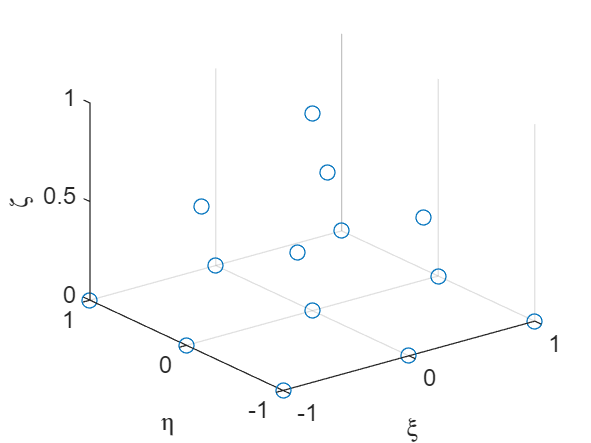

plot3(double(P_Nodes(:,1)),double(P_Nodes(:,2)),double(P_Nodes(:,3)),'o')

set(gca,'XGrid','on','YGrid','on','ZGrid','off')
xlabel('\xi')
ylabel('\eta')
zlabel('\zeta')